## Support Vector Machines

## Support Vector Machines

### Example dataset 1

We will begin with a 2D example dataset which can be separated by a linear boundary. The code below will plot the training data (Figure 1). In this dataset, the positions of the positive examples (indicated with +) and the negative examples (indicated with o) suggest a natural separation indicated by the gap. However, notice that there is an outlier positive example (+) on the far left at about (0:1; 4:1). As part of this exercise, we will also see how this outlier affects the SVM decision boundary.

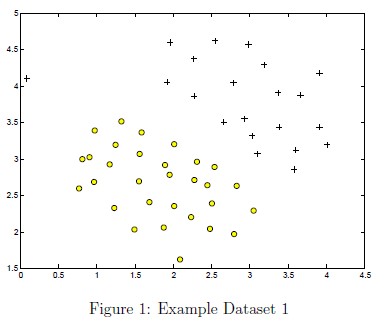

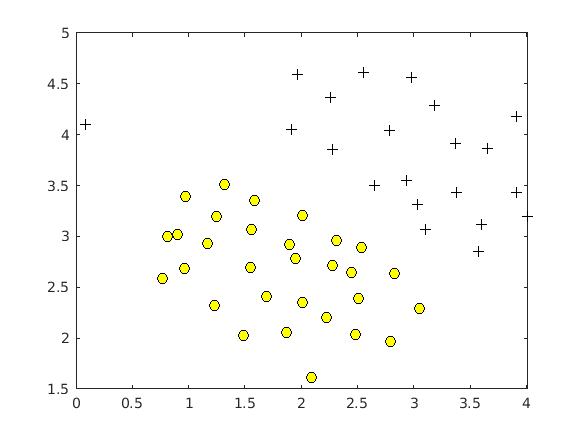

% Load from ex6data1: 
% we will have X, y in wer environment
load('ex6data1.mat');

% Plot training data
plotData(X, y);

    We will try using different values of the $C$ parameter with SVMs. Informally, the $C$ parameter is a positive value that controls the penalty for misclassiffed training examples. A large $C$ parameter tells the SVM to try to classify all the examples correctly. $C$ plays a role similar to $1/\lambda$, where $\lambda$ is the regularization parameter that we were using previously for logistic regression. The code below will run the SVM training (with $C = 1$) using SVM software that we have included with the starter code, `svmTrain.m*`. 

**Implementation Note:** Most SVM software packages (including `svmTrain.m`) automatically add the extra feature $x_0 = 1$ for we and automatically take care of learning the intercept term $\theta_0$. So when passing wer training data to the SVM software, there is no need to add this extra feature $x_0 = 1$ werself. In particular, in MATLAB wer code should be working with training examples $x\in\mathbb{R}^n$ (rather than $x\in\mathbb{R}^{n+1}$) for example, in the first example dataset $x\in\mathbb{R}^2.$

C = 1;
model = svmTrain(X, y, C, @linearKernel, 1e-3, 20);


Training ......................................................................
..................................................... Done! 



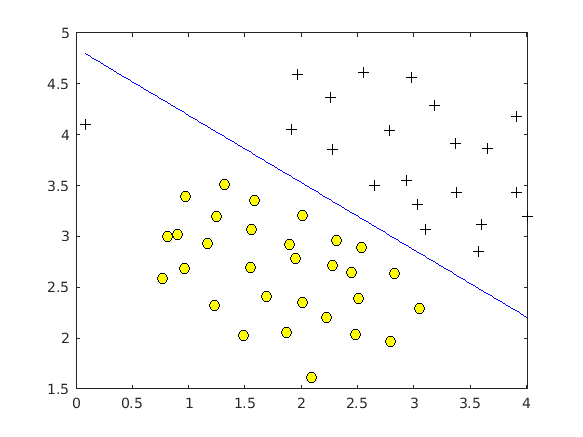

visualizeBoundaryLinear(X, y, model);

When $C = 1$, we should find that the SVM puts the decision boundary in the gap between the two datasets and misclassifies the data point on the far left (Figure 2).

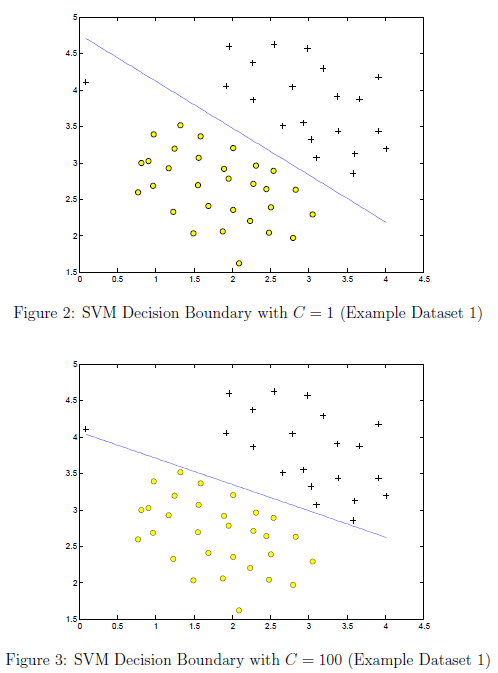

wer task is to try different values of $C$ on this dataset. Specifically, use the control to change the value of $C$ in the script to $C = 100$ and run the SVM training code in the previous section again. When $C = 100$, we should find that the SVM now classifies every single example correctly, but has a decision boundary that does not appear to be a natural fit for the data (Figure 3).

### SVM with gaussian kernels

We will be using SVMs to do non-linear classification. In particular, we will be using SVMs with Gaussian kernels on datasets that are not linearly separable.

#### 1.2.1 Gaussian kernel

To find nonlinear decision boundaries with the SVM, we need to first implement a Gaussian kernel. we can think of the Gaussian kernel as a similarity function that measures the 'distance' between a pair of examples, $(x^{(i)}, x^{(j)})$. The Gaussian kernel is also parameterized by a bandwidth parameter, $\sigma$, which determines how fast the similarity metric decreases (to 0) as the examples are further apart.

The Gaussian kernel function is dened as:


$$K_{gaussian}(x^{(i)},x^{(j)})
=\exp\left(-\frac{\left\| x^{(i)}-x^{(j)}\right\|^2}{2\sigma^2}\right)
=\exp\left(-\frac{\sum_{k=1}^n{(x_k^{(i)}-x_k^{(j)})^2}}{2\sigma^2}\right)$$


x1 = [1 2 1]; x2 = [0 4 -1]; sigma = 2;
sim = gaussianKernel(x1, x2, sigma);

fprintf('Gaussian Kernel between x1 = [1; 2; 1], x2 = [0; 4; -1], sigma = 0.5 : \n\t%f\n', sim);

Gaussian Kernel between x1 = [1; 2; 1], x2 = [0; 4; -1], sigma = 0.5 : 
	0.324652


*we should now submit wer solutions.  Enter *`submit`* at the command prompt, then enter or confirm wer login and token when prompted.*

#### Example dataset

The next code section will load and plot dataset 2 (Figure 4). From the figure, we can observe that there is no linear decision boundary that separates the positive and negative examples for this dataset. 

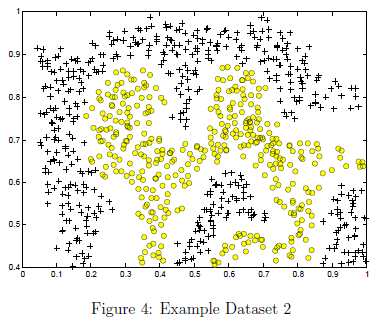

However, by using the Gaussian kernel with the SVM, we will be able to learn a non-linear decision boundary that can perform reasonably well for the dataset.

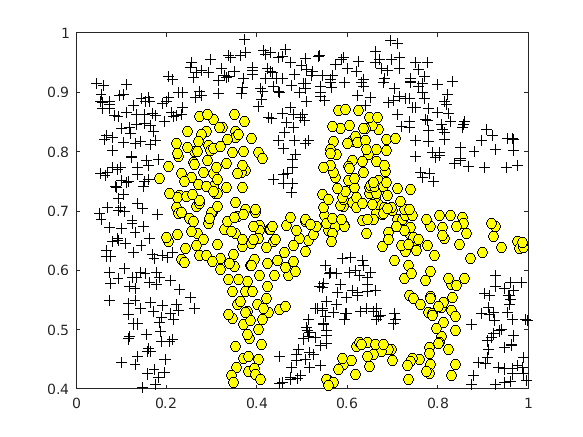

% Load from ex6data2: 
% we will have X, y in wer environment
load('ex6data2.mat');

% Plot training data
plotData(X, y);   

 If we have correctly implemented the Gaussian kernel function, the code below will proceed to train the SVM with the Gaussian kernel on this dataset.

% SVM Parameters
C = 1; sigma = 0.1;

% We set the tolerance and max_passes lower here so that the code will run faster. However, in practice, 
% we will want to run the training to convergence.
model= svmTrain(X, y, C, @(x1, x2) gaussianKernel(x1, x2, sigma)); 


Training ......................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
................................. Done! 



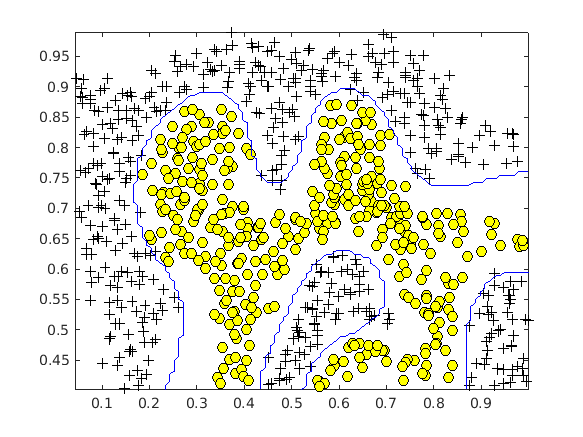

visualizeBoundary(X, y, model);

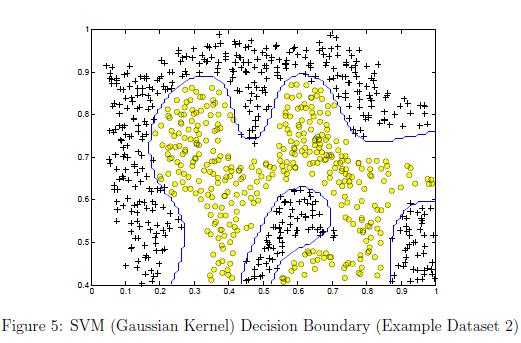

Figure 5 shows the decision boundary found by the SVM with a Gaussian kernel. The decision boundary is able to separate most of the positive and negative examples correctly and follows the contours of the dataset well.

#### Example dataset 3

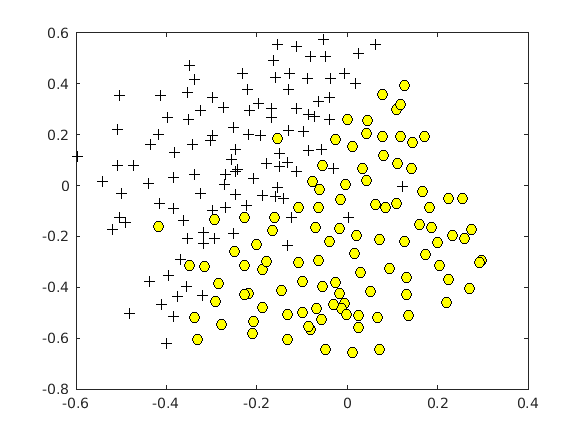

load('ex6data3.mat');

plotData(X, y);

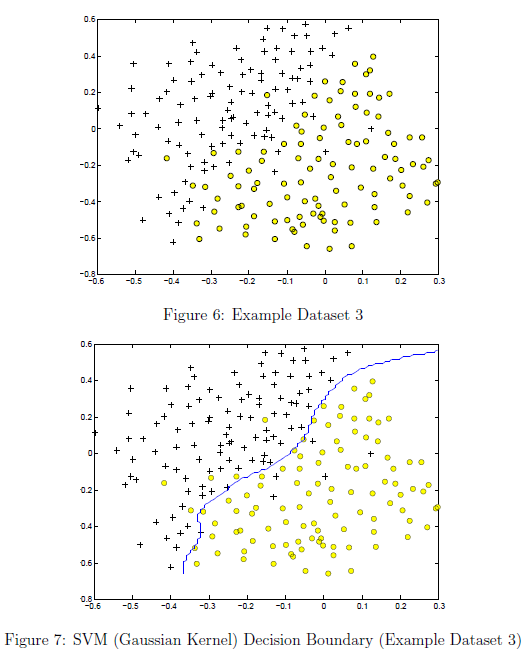

In the provided dataset, `ex6data3.mat`, we are given the variables `X`, `y`, `Xval`, `yval`. The provided code will train the SVM classifier using the training set (`X,y`) using parameters loaded from `dataset3Params.m`. 

    wer task is to use the cross validation set `Xval`, `yval` to determine the best $C$ and $\sigma$ parameter to use. we should write any additional code necessary to help we search over the parameters $C$ and $\sigma$. For both $C$ and $\sigma$ we suggest trying values in multiplicative steps (e.g., 0.01, 0,03, 0.1, 0.3, 1, 3, 10, 30). Note that we should try all possible pairs of values for $C$ and $\sigma$ (e.g., $C = 0.3$ and $\sigma= 0.1$). 

% Try different SVM Parameters here
[C, sigma] = dataset3Params(X, y, Xval, yval);

Cselect =          0    0.0100    3.0000    0.1000    0.3000    1.0000    3.0000   10.0000   30.0000


sigmas =     8.0000    0.0100    3.0000    0.1000    0.3000    1.0000    3.0000   10.0000   30.0000


maximumerr = 1000


Training ........ Done! 


Training ........ Done! 


Training ........ Done! 


Training ........ Done! 


Training ........ Done! 


Training ........ Done! 


Training ........ Done! 


Training ........ Done! 


Training ........ Done! 


Training ...................................................... Done! 


Training ......... Done! 


Training ............................................................. Done! 


Training .............................................. Done! 


Training .......................................... Done! 


Training ................................................. Done! 


Training ......................................... Done! 


Training ............................................. Done! 


Training ................................................... Done! 


Training ............................................ Done! 


Training ......... Done! 


Training ..................................................................... Done! 


Training


% Train the SVM
model = svmTrain(X, y, C, @(x1, x2)gaussianKernel(x1, x2, sigma));


Training ......................................................................
...............................................................................
...............................................................................
...............................................................................
................................................ Done! 



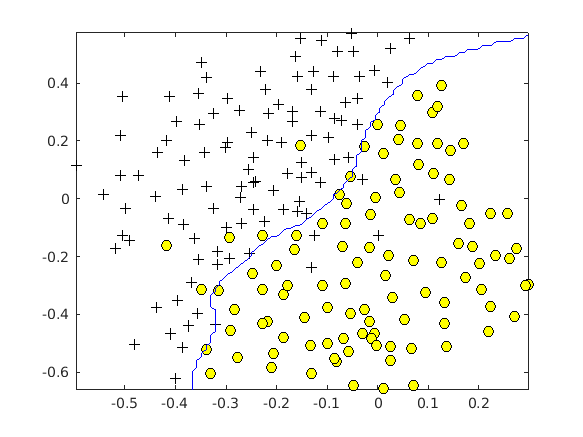

visualizeBoundary(X, y, model);

## Spam Classification

Many email services today provide spam filters that are able to classify emails into spam and non-spam email with high accuracy. In this part of the exercise, we will use SVMs to build wer own spam filter. we will be training a classifier to classify whether a given email, $x$, is spam ($y = 1$) or non-spam ($y = 0$). In particular, we need to convert each email into a feature vector $x\in\mathbb{R}^n$. The following parts of the exercise will walk we through how such a feature vector can be constructed from an email.

    The dataset included for this exercise is based on a a subset of the [SpamAssassin Public Corpus](https://spamassassin.apache.org/old/publiccorpus/). For the purpose of this exercise, we will only be using the body of the email (excluding the email headers).

### Preprocessing emails

Before starting on a machine learning task, it is usually insightful to take a look at examples from the dataset. Figure 8 shows a sample email that contains a URL, an email address (at the end), numbers, and dollar amounts. While many emails would contain similar types of entities (e.g., numbers, other URLs, or other email addresses), the specific entities (e.g., the specic URL or specific dollar amount) will be different in almost every email.

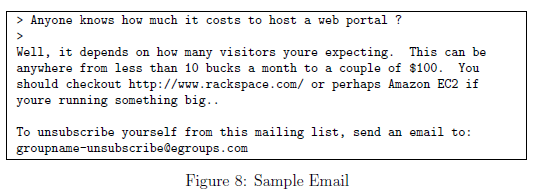

    Therefore, one method often employed in processing emails is to 'normalize' these values, so that all URLs are treated the same, all numbers are treated the same, etc. For example, we could replace each URL in the email with the unique string "httpaddr" to indicate that a URL was present. This has the effect of letting the spam classifier make a classification decision based on whether any URL was present, rather than whether a specific URL was present. This typically improves the performance of a spam classifier, since spammers often randomize the URLs, and thus the odds of seeing any particular URL again in a new piece of spam is very small.

    In `processEmail.m`, we have implemented the following email preprocessing and normalization steps:

- Lower-casing: The entire email is converted into lower case, so that captialization is ignored (e.g., IndIcaTE is treated the same as indicate).

- Stripping HTML: All HTML tags are removed from the emails. Many emails often come with HTML formatting; we remove all the HTML tags, so that only the content remains.

- Normalizing URLs: All URLs are replaced with the text "httpaddr".

- Normalizing Email Addresses: All email addresses are replaced with the text "emailaddr".

- Normalizing Numbers: All numbers are replaced with the text 'number'.

- Normalizing Dollars: All dollar signs ($) are replaced with the text 'dollar'.

- Word Stemming: Words are reduced to their stemmed form. For example, 'discount', 'discounts', 'discounted' and 'discounting' are all replaced with 'discount'. Sometimes, the Stemmer actually strips off additional characters from the end, so 'include', 'includes', 'included', and 'including' are all replaced with 'includ'.

- Removal of non-words: Non-words and punctuation have been removed. All white spaces (tabs, newlines, spaces) have all been trimmed to a single space character.

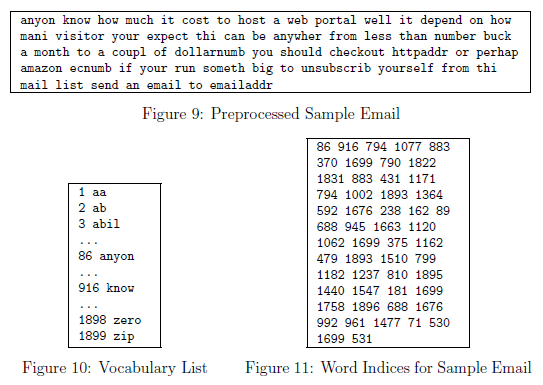

    The result of these preprocessing steps is shown in Figure 9. While preprocessing has left word fragments and non-words, this form turns out to be much easier to work with for performing feature extraction.

#### 2.1.1 Vocabulary list

After preprocessing the emails, we have a list of words (e.g., Figure 9) for each email. The next step is to choose which words we would like to use in our classifier and which we would want to leave out. For this exercise, we have chosen only the most frequently occuring words as our set of words considered (the vocabulary list). Since words that occur rarely in the training set are only in a few emails, they might cause the model to overfit our training set. The complete vocabulary list is in the file vocab.txt and also shown in Figure 10. Our vocabulary list was selected by choosing all words which occur at least a 100 times in the spam corpus, resulting in a list of 1899 words. In practice, a vocabulary list with about 10,000 to 50,000 words is often used.

    Given the vocabulary list, we can now map each word in the preprocessed emails (e.g., Figure 9) into a list of word indices that contains the index of the word in the vocabulary list. Figure 11 shows the mapping for the sample email. Specically, in the sample email, the word 'anyone' was first normalized to 'anyon' and then mapped onto the index 86 in the vocabulary list.

    We are given a string `str` which is a single word from the processed email. we should look up the word in the vocabulary list `vocabList` and find if the word exists in the vocabulary list. If the word exists, we should add the index of the word into the word indices variable. If the word does not exist, and is therefore not in the vocabulary, we can skip the word.

clear;

% Extract Features
file_contents = readFile('emailSample1.txt');
word_indices  = processEmail(file_contents);
% Print Stats
disp(word_indices)

*we should now submit wer solutions.  Enter *`submit`* at the command prompt, then enter or confirm wer login and token when prompted.*

### 2.2 Extracting features from emails

we will now implement the feature extraction that converts each email into a vector in $\mathbb{R}^n$. For this exercise, we will be using words in vocabulary list. Specically, the feature $x_i\in\{0,\;1\}$for an email corresponds to whether the $i$-th word in the dictionary occurs in the email. That is, $x_i = 1$ if the $i$-th word is in the email and $x_i = 0$ if the $i$-th word is not present in the email.

    Thus, for a typical email, this feature would look like:


$$x=\left\lbrack \begin{array}{c}
0\\
\vdots \\
1\\
0\\
\vdots \\
1\\
0\\
\vdots \\
0
\end{array}\right\rbrack \in R^n$$


we should now complete the code in `emailFeatures.m` to generate a feature vector for an email, given the word indices. Once we have implemented `emailFeatures.m`, the code below will will run wer code on the email sample. we should see that the feature vector had length 1899 and 45 non-zero entries.

% Extract Features
features = emailFeatures(word_indices);

% Print Stats
fprintf('Length of feature vector: %d\n', length(features));

Error using load
Unable to read file 'spamTrain.mat'. No such file or directory.

fprintf('Number of non-zero entries: %d\n', sum(features > 0));

### 2.3 Training SVM for spam classification

After we have completed the feature extraction functions, the code in this section will load a preprocessed training dataset that will be used to train an SVM classifier. `spamTrain.mat` contains 4000 training examples of spam and non-spam email, while `spamTest.mat` contains 1000 test examples. Each original email was processed using the `processEmail` and `emailFeatures `functions and converted into a vector $x^{(i)}\in\mathbb{R}^{1899|$. After loading the dataset, the code will proceed to train a SVM to classify between spam ($y = 1$) and non-spam ($y = 0$) emails. Once the training completes, we should see that the classifier gets a training accuracy of about 99.8% and a test accuracy of about 98.5%.

% Load the Spam Email dataset
% we will have X, y in wer environment
load('spamTrain.mat');
C = 0.1;
model = svmTrain(X, y, C, @linearKernel);

p = svmPredict(model, X);
fprintf('Training Accuracy: %f\n', mean(double(p == y)) * 100);

% Load the test dataset
% we will have Xtest, ytest in wer environment
load('spamTest.mat');

p = svmPredict(model, Xtest);
fprintf('Test Accuracy: %f\n', mean(double(p == ytest)) * 100);

### 2.4 Top predictors for spam

To better understand how the spam classifier works, we can inspect the parameters to see which words the classifier thinks are the most predictive of spam. The code below finds the parameters with the largest positive values in the classier and displays the corresponding words (Figure 12). Thus, if an email contains words such as 'guarantee', 'remove', 'dollar', and 'price' (the top predictors shown in Figure 12), it is likely to be classied as spam.

% Sort the weights and obtin the vocabulary list
[weight, idx] = sort(model.w, 'descend');
vocabList = getVocabList();
for i = 1:15
    if i == 1
        fprintf('Top predictors of spam: \n');
    end
    fprintf('%-15s (%f) \n', vocabList{idx(i)}, weight(i));
end